
%Generate random signal
t = (0:0.001:1)';
S1 = 2*randn(size(t));

%Trunk 50 samples  
S1 = S1(1:50);
%Create delayed signal
S2 = S1; 
S2 = [zeros(10,1); S2(1:40)]; %Add zeros at the beginning
subplot(3,1,1)
plot(1:50,S1)
subplot(3,1,2)
plot(1:50,S2)

%Calculate cross-correlation
[r1,n] = xcorr(S1,S2);
subplot(3,1,3)
plot(n,r1)
%And delay
[m,p] = max(r1)

m = 125.6062

p = 40

delay = n(1,p)

delay = -10

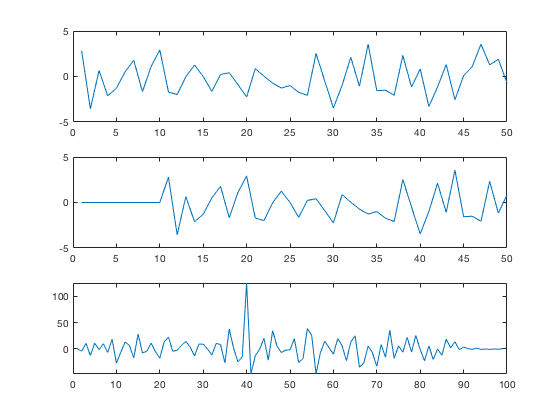

%[r2] = normxcorr2(yn,zn);

%subplot(3,1,3)
%plot(n,r2)
%plot(r2)
S2 = S2 + 0.8*randn(size(S2));
subplot(3,1,2)
[r1,n] = xcorr(S1,S2);
subplot(3,1,3)
%plot(zn)
%subplot(1,2,2)
plot(r1)